# **RS-HL-2: Generate Contact Chart of Given Constellation**

**Hongseok Kim**

**Ver 1.1**

**Last Revised: 6/7/2024**

## Revision History

Ver 1.0: Initial Draft [6/5/2024]

Ver 1.1: Added several functions [6/7/2024]

## Scope

## Interface Specification

clc; clear;
addpath('~/Desktop/Redstone_Project/RS_HL/RS_HL_1_Constellation_Scinario_Formulation/')

## I. Input information

### I.1 Time Parameter

% Initial Epoch Definition

Year = 2024;
Month = 3;
Day = 21;
Hour = 0;
Minute = 0;
Seconds = 0;

% Duration and Steptime
duration = hours(24);
steptime = 15; % seconds

startTime = datetime(Year,Month,Day,Hour,Minute,Seconds);

time_parameters.startTime = datetime(Year,Month,Day,Hour,Minute,Seconds);
time_parameters.duration = duration;
time_parameters.steptime = steptime;

scenario = scenario_initalization(time_parameters);



### I.2 Satellite Constellation - Walker Configuration (24 SATs in Single Orbit)

% Intial Orbit Settings

Altitude = 500; % (km)
Eccentricity = 1e-5;
Inclinaton = 97.4022; % (deg)
RAAN = 90;  % (deg)
AOP = 0; % (deg)

% Number of satellites
number_of_SATs = 24;

% Satellite Characteristics - This will entail -1, -2, ... for
% constallation
satellite_name = "RS-1";

% Orbit Propagator
Orbit_Propagator = 'SGP4';


orbit_information.SMA = Altitude*1000 + 6378000;
orbit_information.ecc = Eccentricity;
orbit_information.inc = Inclinaton;
orbit_information.RAAN = RAAN;
orbit_information.AOP = AOP;

% Generate First Stream of Satellites
satellites_orbit_1 = single_orbit_constellation(scenario, orbit_information, number_of_SATs, Orbit_Propagator, satellite_name);


% Generate Second Steram of Satellites
RAAN = 105;
orbit_information.RAAN = RAAN;
satellite_name = "RS-2";
satellites_orbit_2 = single_orbit_constellation(scenario, orbit_information, number_of_SATs, Orbit_Propagator, satellite_name);

% Merge Satellite Informations
satellites = [satellites_orbit_1, satellites_orbit_2];



### I.4 gs Station Location

gs_info = ["Austin", 30.2672, -97.7431, 15;
           "New York", 40.7128, -74.0060, 10;
           "Los Angeles", 34.0522, -118.4837, 71;
           "Chicago", 41.8781, -87.6298, 181;
           "Houston", 29.7604, -95.3698, 30;
           "Phoenix", 33.4484, -112.0740, 331;
           "Philadelphia", 39.9526, -75.1652, 12;
           "San Antonio", 29.4481, -98.4936, 198;
           "San Diego", 32.7157, -117.1611, 22;
           "Dallas", 32.7767, -96.7970, 137;
           "London", 51.5074, -0.1278, 35;
           "Tokyo", 35.6895, 139.6917, 6;
           "Paris", 48.8566, 2.3522, 35;
           "Moscow", 55.7558, 37.6176, 155;
           "Sydney", -33.8688, 151.2093, 19;
           "Toronto", 43.6511, -79.3830, 76;
           "Berlin", 52.5200, 13.4050, 34;
           "Rome", 41.9028, 12.4964, 17;
           "Seoul", 37.5665, 126.9780, 23;
           "Mumbai", 19.0760, 72.8777, 14;
           "Beijing", 39.9042, 116.4074, 43;
           "Mexico City", 19.4326, -99.1332, 2240;
           "São Paulo", -23.5505, -46.6333, 780;
           "Bangkok", 13.7563, 100.5018, 2;
           "Istanbul", 41.0082, 28.9784, 39;
           "Cairo", 30.0444, 31.2357, 23;
           "Dubai", 25.2769, 55.2963, 4;
           "Singapore", 1.3521, 103.8198, 15;
           "Hong Kong", 22.3193, 114.1694, 39;
           "Sydney", -33.8688, 151.2093, 19];



gs = groundStation(scenario,"Name",gs_info(:,1), ...
                        "Latitude",str2double(gs_info(:,2)), ...
                        "Longitude", str2double(gs_info(:,3)), ...
                        "Altitude", str2double(gs_info(:,4)), ...
                        "MinElevationAngle", 15);


## II. GS to Satellite Access Information Generation


[time_vector, ...
  gs_to_sat_access_table, ...
  gs_to_sat_access_matrix, ...
  gs_to_sat_access_info, ...
  contact_1_sat, ...
  contact_2_sat, ...
  contact_3_sat, ...
  contact_4_plus_sat] = gs_to_sat_access_info_generation(scenario,satellites,gs)

time_vector = 1×5761 datetime array
Columns 1 through 1424

   21-Mar-2024 00:00:00   21-Mar-2024 00:00:15   21-Mar-2024 00:00:30   21-Mar-2024 00:00:45   21-Mar-2024 00:01:00   21-Mar-2024 00:01:15   21-Mar-2024 00:01:30   21-Mar-2024 00:01:45   21-Mar-2024 00:02:00   21-Mar-2024 00:02:15   21-Mar-2024 00:02:30   21-Mar-2024 00:02:45   21-Mar-2024 00:03:00   21-Mar-2024 00:03:15   21-Mar-2024 00:03:30   21-Mar-2024 00:03:45   21-Mar-2024 00:04:00   21-Mar-2024 00:04:15   21-Mar-2024 00:04:30   21-Mar-2024 00:04:45   21-Mar-2024 00:05:00   21-Mar-2024 00:05:15   21-Mar-2024 00:05:30   21-Mar-2024 00:05:45   21-Mar-2024 00:06:00   21-Mar-2024 00:06:15   21-Mar-2024 00:06:30   21-Mar-2024 00:06:45   21-Mar-2024 00:07:00   21-Mar-2024 00:07:15   21-Mar-2024 00:07:30   21-Mar-2024 00:07:45   21-Mar-2024 00:08:00   21-Mar-2024 00:08:15   21-Mar-2024 00:08:30   21-Mar-2024 00:08:45   21-Mar-2024 00:09:00   21-Mar-2024 00:09:15   21-Mar-2024 00:09:30   21-Mar-2024 00:09:45   21-Mar-2024 00:10

gs_to_sat_access_table = 3611×8 table
     Source      Target     IntervalNumber         StartTime                EndTime           Duration    StartOrbit    EndOrbit
    ________    ________    ______________    ____________________    ____________________    ________    __________    ________

    "Austin"    "RS-1-1"          1           21-Mar-2024 00:05:15    21-Mar-2024 00:11:00      345            1            1   
    "Austin"    "RS-1-1"          2           21-Mar-2024 13:13:45    21-Mar-2024 13:19:00      315            9            9   
    "Austin"    "RS-1-1"          3           21-Mar-2024 23:46:15    21-Mar-2024 23:50:45      270           16           16   
    "Austin"    "RS-1-2"          1         

gs_to_sat_access_matrix =      1     1     1     1     1     1     2     2     2     2     2     2     2     1     1     1     1     1     1     1     1     2     2     2     2     2     2     2     2     1     1     1     1     1     1     1     1     2     2     2     2     2     2     2     2     1     1     1     1     1
     2     2     2     2     2     2     2     1     1     1     1     1     1     1     1     1     2     2     2     2     2     2     1     1     1     1     1     1     1     1     1     1     1     2     2     2     2     1     1     1     1     1     1     1     1     1     1     1     1     2
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     2     2     3     3     4     4     4     3     3     3     2     

gs_to_sat_access_info =   1x48 Access array with properties:

    Sequence
    LineWidth
    LineColor


contact_1_sat =      1     1
     2     1
     3     1
     4     1
     5     1
     6     1
    14     1
    15     1
    16     1
    17     1


contact_2_sat =      7     1
     8     1
     9     1
    10     1
    11     1
    12     1
    13     1
    22     1
    23     1
    24     1


contact_3_sat =    116     1
   117     1
   118     1
   119     1
   132     1
   133     1
   134     1
   135     1
   136     1
   148     1


contact_4_plus_sat =    169     1
   183     1
   184     1
   198     1
   199     1
   200     1
   213     1
   214     1
   215     1
   229     1


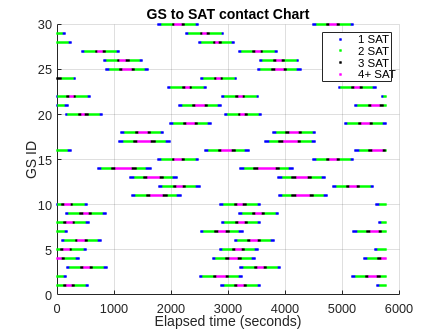



figure;
scatter(contact_1_sat(:,1),contact_1_sat(:,2),'.','b')
hold on
scatter(contact_2_sat(:,1),contact_2_sat(:,2),'.','g')
scatter(contact_3_sat(:,1),contact_3_sat(:,2),'.','k')
scatter(contact_4_plus_sat(:,1),contact_4_plus_sat(:,2),'.','m')
hold off
title('GS to SAT contact Chart')
xlabel('Elapsed time (seconds)')
ylabel('GS ID')
legend('1 SAT', '2 SAT', '3 SAT', '4+ SAT')
grid on

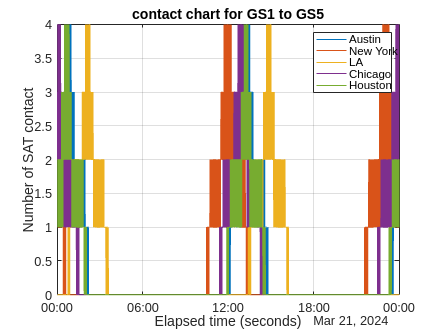


figure;
plot(time_vector,gs_to_sat_access_matrix(1,:))
hold on
plot(time_vector,gs_to_sat_access_matrix(2,:))
plot(time_vector,gs_to_sat_access_matrix(3,:))
plot(time_vector,gs_to_sat_access_matrix(4,:))
plot(time_vector,gs_to_sat_access_matrix(5,:))
hold off
title('contact chart for GS1 to GS5')
xlabel('Elapsed time (seconds)')
ylabel('Number of SAT contact')
legend('Austin', 'New York', 'LA', 'Chicago', 'Houston')
grid on

## III. Satellite to gs Acces Information Generation

[time_vector, ...
 sat_to_gs_access_table, ...
 sat_to_gs_access_matrix, ...
 sat_to_gs_access_info, ...
 contact_1_gs, ...
 contact_2_gs, ...
 contact_3_gs, ...
 contact_4_plus_gs] = sat_to_gs_access_info_generation(scenario,satellites,gs)

time_vector = 1×5761 datetime array
Columns 1 through 1424

   21-Mar-2024 00:00:00   21-Mar-2024 00:00:15   21-Mar-2024 00:00:30   21-Mar-2024 00:00:45   21-Mar-2024 00:01:00   21-Mar-2024 00:01:15   21-Mar-2024 00:01:30   21-Mar-2024 00:01:45   21-Mar-2024 00:02:00   21-Mar-2024 00:02:15   21-Mar-2024 00:02:30   21-Mar-2024 00:02:45   21-Mar-2024 00:03:00   21-Mar-2024 00:03:15   21-Mar-2024 00:03:30   21-Mar-2024 00:03:45   21-Mar-2024 00:04:00   21-Mar-2024 00:04:15   21-Mar-2024 00:04:30   21-Mar-2024 00:04:45   21-Mar-2024 00:05:00   21-Mar-2024 00:05:15   21-Mar-2024 00:05:30   21-Mar-2024 00:05:45   21-Mar-2024 00:06:00   21-Mar-2024 00:06:15   21-Mar-2024 00:06:30   21-Mar-2024 00:06:45   21-Mar-2024 00:07:00   21-Mar-2024 00:07:15   21-Mar-2024 00:07:30   21-Mar-2024 00:07:45   21-Mar-2024 00:08:00   21-Mar-2024 00:08:15   21-Mar-2024 00:08:30   21-Mar-2024 00:08:45   21-Mar-2024 00:09:00   21-Mar-2024 00:09:15   21-Mar-2024 00:09:30   21-Mar-2024 00:09:45   21-Mar-2024 00:10

sat_to_gs_access_table = 3611×8 table
     Source        Target        IntervalNumber         StartTime                EndTime           Duration    StartOrbit    EndOrbit
    ________    _____________    ______________    ____________________    ____________________    ________    __________    ________

    "RS-1-1"    "Austin"               1           21-Mar-2024 00:05:15    21-Mar-2024 00:11:00      345            1            1   
    "RS-1-1"    "Austin"               2           21-Mar-2024 13:13:45    21-Mar-2024 13:19:00      315            9            9   
    "RS-1-1"    "Austin"               3           21-Mar-2024 23:46:15    21-Mar-2024 23:50:45      270           16           16   
    "RS-1-1"    "Ne

sat_to_gs_access_matrix =      0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     2     4     4     4     5     5     5     5     5     5     5     5     5     4     4     5     5     5     5     5     5     5     5     5     3     2     2     1     1     1
     1     1     1     1     1     2     4     4     5     5     5     5     5     5     5     5     4     4     5     5     5     5     5     5     5     5     5     5     3     2     2     2     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0
     4     4     5     5     5     5     5     5     5     5     5     5     4     2     2     2     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     0     0     0     0     

sat_to_gs_access_info =   1x30 Access array with properties:

    Sequence
    LineWidth
    LineColor


contact_1_gs =     13     1
    14     1
    15     1
    16     1
    17     1
    18     1
    19     1
    20     1
    48     1
    49     1


contact_2_gs =     21     1
    46     1
    47     1
   425     1
   899     1
   900     1
   907     1
   908     1
   909     1
   910     1


contact_3_gs =     45     1
   404     1
   405     1
   406     1
   407     1
   408     1
   409     1
   410     1
   411     1
   412     1


contact_4_plus_gs =     22     1
    23     1
    24     1
    25     1
    26     1
    27     1
    28     1
    29     1
    30     1
    31     1


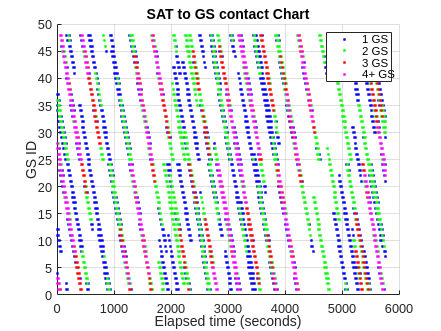




figure;
scatter(contact_1_gs(:,1),contact_1_gs(:,2),'.','b')
hold on
scatter(contact_2_gs(:,1),contact_2_gs(:,2),'.','g')
scatter(contact_3_gs(:,1),contact_3_gs(:,2),'.','r')
scatter(contact_4_plus_gs(:,1),contact_4_plus_gs(:,2),'.','m')
hold off
grid on
title('SAT to GS contact Chart')
xlabel('Elapsed time (seconds)')
ylabel('GS ID')
legend('1 GS', '2 GS', '3 GS', '4+ GS')
grid on

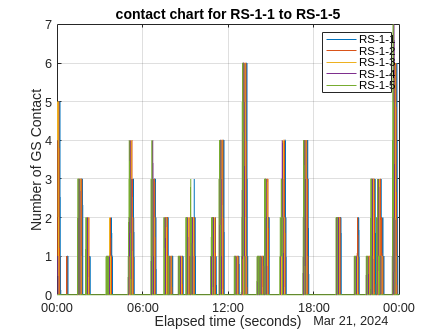



figure;
plot(time_vector,sat_to_gs_access_matrix(1,:))
hold on
plot(time_vector,sat_to_gs_access_matrix(2,:))
plot(time_vector,sat_to_gs_access_matrix(3,:))
plot(time_vector,sat_to_gs_access_matrix(4,:))
plot(time_vector,sat_to_gs_access_matrix(5,:))
hold off
title('contact chart for RS-1-1 to RS-1-5')
xlabel('Elapsed time (seconds)')
ylabel('Number of GS Contact')
legend('RS-1-1', 'RS-1-2', 'RS-1-3', 'RS-1-4', 'RS-1-5')
grid on

## IV. 3D Data Visualization

figure;


% play(scenario)

## V. Data Analysis